# Problem 1: Lead Compensator for Speed Improvement

## Baseline PID Performance:

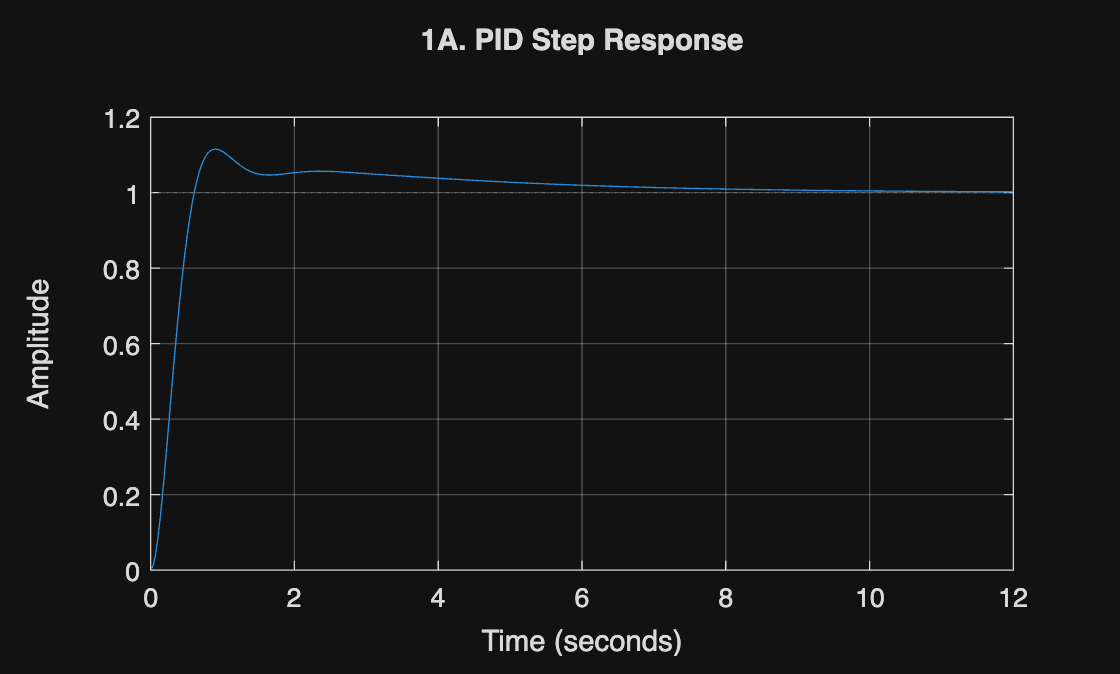

G = tf(20,[1 7 10 0 ]); % Defining Transfer Function
C_pid = pidtune(G,'PID'); % PID Auto Tuner
sys = feedback(G * C_pid, 1); % Closed-Loop System
% step response
figure;
step(sys);
title('1A. PID Step Response');
grid on;

info = stepinfo(sys);
fprintf('Rise Time: %.3f s\n', info.RiseTime);

Rise Time: 0.408 s


fprintf('Settling Time: %.3f s\n', info.SettlingTime);

Settling Time: 5.951 s


fprintf('Overshoot: %.2f%%\n', info.Overshoot);

Overshoot: 11.54%


## Lead Compensator Design

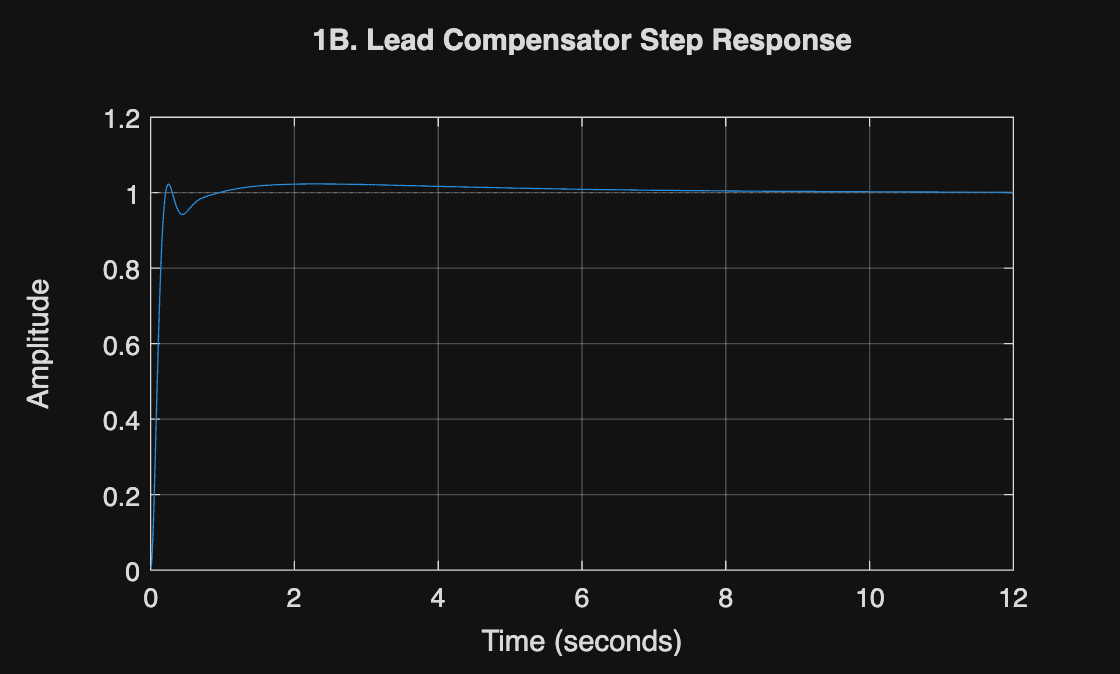

s = tf('s');
Kc = 11;
C_lead = Kc * (s + 3)/(s + 15); % Lead Compensator
C_total = C_pid * C_lead;
sys2 = feedback(G * C_total, 1);
% step response
figure;
step(sys2);
title('1B. Lead Compensator Step Response');
grid on;

info_lead = stepinfo(sys2);
fprintf('Rise Time: %.3f s\n', info_lead.RiseTime);

Rise Time: 0.132 s


fprintf('Settling Time: %.3f s\n', info_lead.SettlingTime);

Settling Time: 3.338 s


fprintf('Overshoot: %.2f%%\n', info_lead.Overshoot);

Overshoot: 2.32%


## Performance Comparison

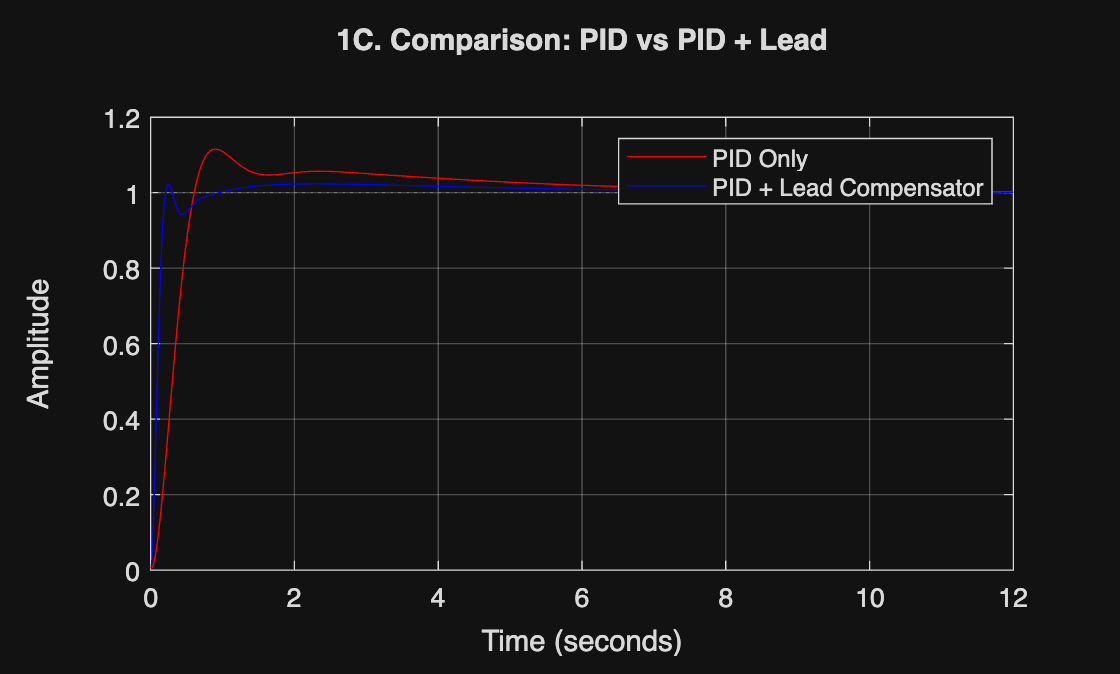

figure;
step(sys, 'r', sys2, 'b');
legend('PID Only', 'PID + Lead Compensator');
title('1C. Comparison: PID vs PID + Lead');
grid on;


% Display Table
ResultsTable = table([info.RiseTime; info.SettlingTime; info.Overshoot], ...
                     [info_lead.RiseTime; info_lead.SettlingTime; info_lead.Overshoot], ...
                     'VariableNames', {'PID Only', 'PID + Lead'}, ...
                     'RowNames', {'Rise Time (s)', 'Settling Time (s)', 'Overshoot (%)'});
disp(ResultsTable);

                         PID Only    PID + Lead
                         ________    __________

    Rise Time (s)        0.40833      0.13162  
    Settling Time (s)     5.9509       3.3383  
    Overshoot (%)         11.538       2.3245  



The lead compensator improves the transient response by adding phase lead. This increases the damping that reduces overshoot and settling time as well as the bandwidth which results in a shorter rise time.

## Parameter Experimentation

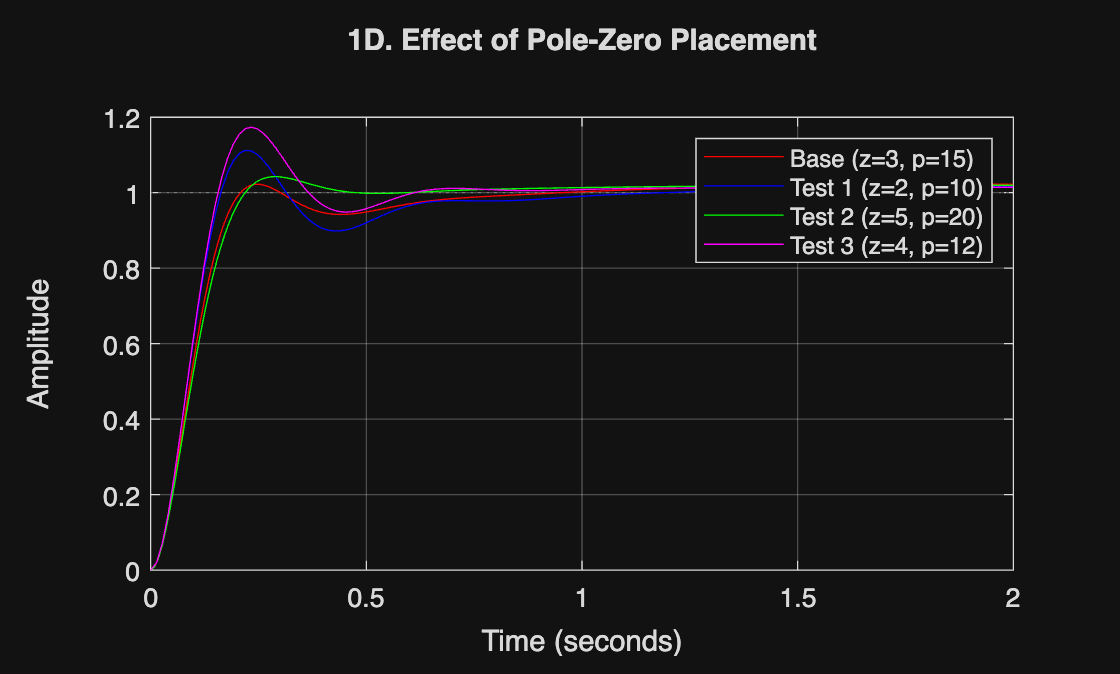

C1 = Kc * (s + 2)/(s + 10);
sys3 = feedback(G * C1 * C_pid, 1);

C2 = Kc * (s + 5)/(s + 20);
sys4 = feedback(G * C2 * C_pid, 1);

C3 = Kc * (s + 4)/(s + 12);
sys5 = feedback(G * C3 * C_pid, 1);

figure;
step(sys2, 'r', sys3, 'b', sys4, 'g', sys5, 'm-', 2);
legend('Base (z=3, p=15)', 'Test 1 (z=2, p=10)', 'Test 2 (z=5, p=20)', 'Test 3 (z=4, p=12)');
title('1D. Effect of Pole-Zero Placement');
grid on;

The placement of the zero and pole directly dictates the trade-off between speed and stability. Moving the zero closer to the origin forces the system to react earlier, reducing rise time. The distance to the compensator pole then determines the 'limit' of this acceleration. A wide gap between the zero and pole provides maximum speed (high phase lead) but can introduce overshoot, whereas a narrow gap offers a conservative improvement that is robust against noise.

#  Problem 2: Lag Compensator for Steady-State Accuracy

## Proportional Controller Analysis

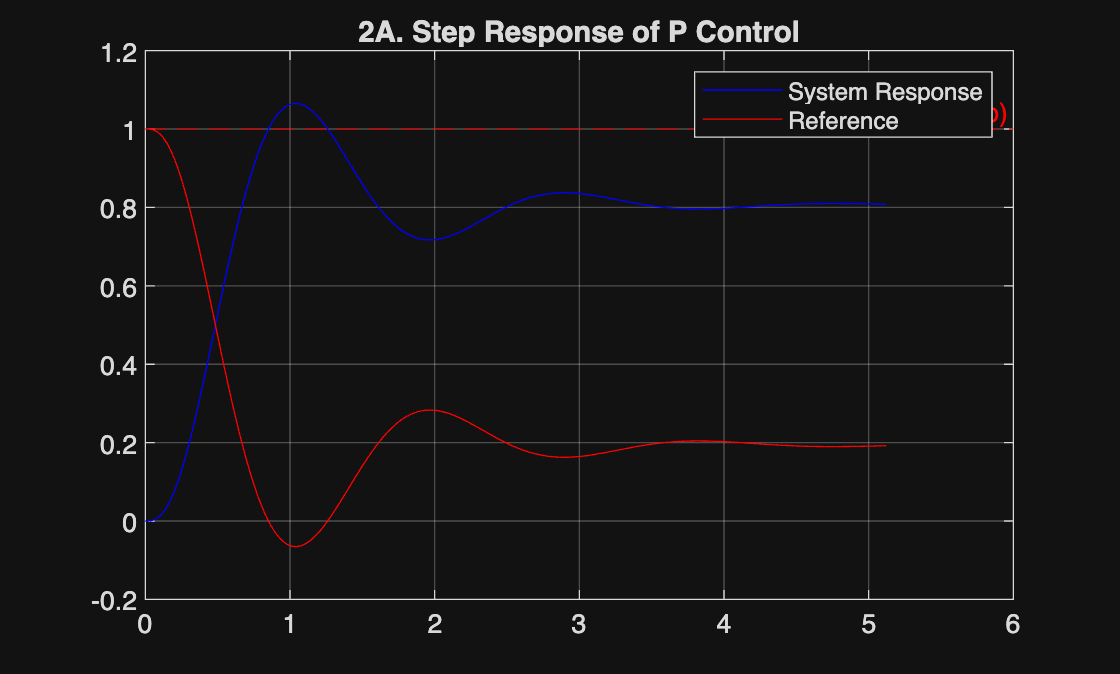

s = tf('s');
G = 50/((s+1)*(s+3)*(s+8));
Kp = 2;
Cp = Kp;
sys = feedback(Cp * G, 1);

[y,t] = step(sys);

figure;
plot(t,y,'b',t,1-y,'r');
legend('P Controller','Error');
title('2A. Step Response of P Control');
grid on;
% Reference line
hold on
yline(1, '--r', 'Reference (Unit Step)')
legend('System Response', 'Reference')


ess_p = 1 - y(end); % Steady State Error
fprintf('Closed-loop Steady State Error: %.4f\n', ess_p);

Closed-loop Steady State Error: 0.1920


## Lag Compensator Design

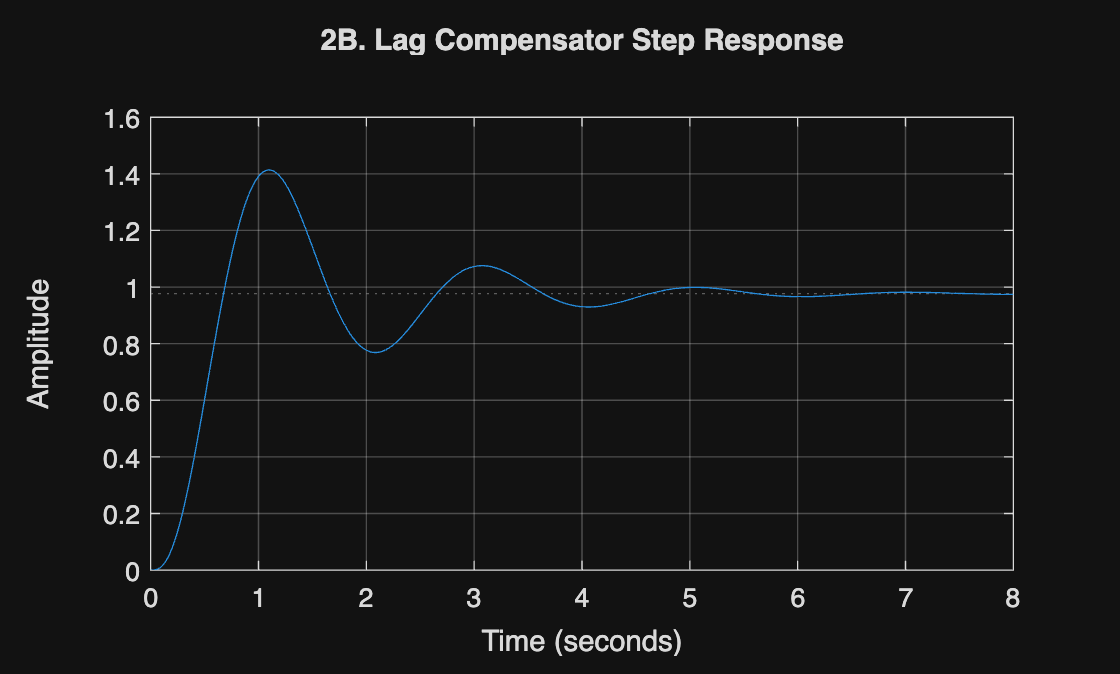

Kc = 1;
C_lag = Kc * (s + 1)/(s + 0.1);
C = Kp * C_lag;
sys2 = feedback(C * G,1);
figure;
step(sys2);
title('2B. Lag Compensator Step Response');
grid on;


[y,~] = step(sys2);
ess_lag = 1 - y(end); % Steady State Error 

## Steady-State Error Reduction

info = stepinfo(sys);
info_lag = stepinfo(sys2);
% Error reduction Percentage
    err_rdn_pcnt = 100 * (ess_p - ess_lag)/ess_p;
% Display Table
ResultsTable = table([ess_p; info.SettlingTime], ...
                     [ess_lag; info_lag.SettlingTime], ...
                     'VariableNames', {'P Only', 'P + Lag'}, ...
                     'RowNames', {'Steady-state error', 'Settling Time (s)'});

                          P Only     P + Lag 
                          _______    ________

    Steady-state error    0.19202    0.025389
    Settling Time (s)      3.2198      5.2126



disp(ResultsTable);
fprintf('Error Reduction Percentage: %.4f\n', err_rdn_pcnt);

Error Reduction Percentage: 86.7778


Lag compensation operates on a fundamental trade-off: it sacrifices some speed for significantly better accuracy. By increasing the gain for slow-moving signals, it effectively eliminates steady-state error. The side effect of this high low-frequency gain is a reduction in system bandwidth, which manifests as a slower response and a longer settling period.

## Trade-off Analysis

1) Does settling time increase?

Yes, a lag compensator introduces a pole close to the origin, which slows down system and lowers the bandwidth, causing the system longer to settle.

2) Is the response slower?

Yes, compared to P-only control, the rise time is higher and the system reacts slower to changes, ultimately, the response time is slower. 

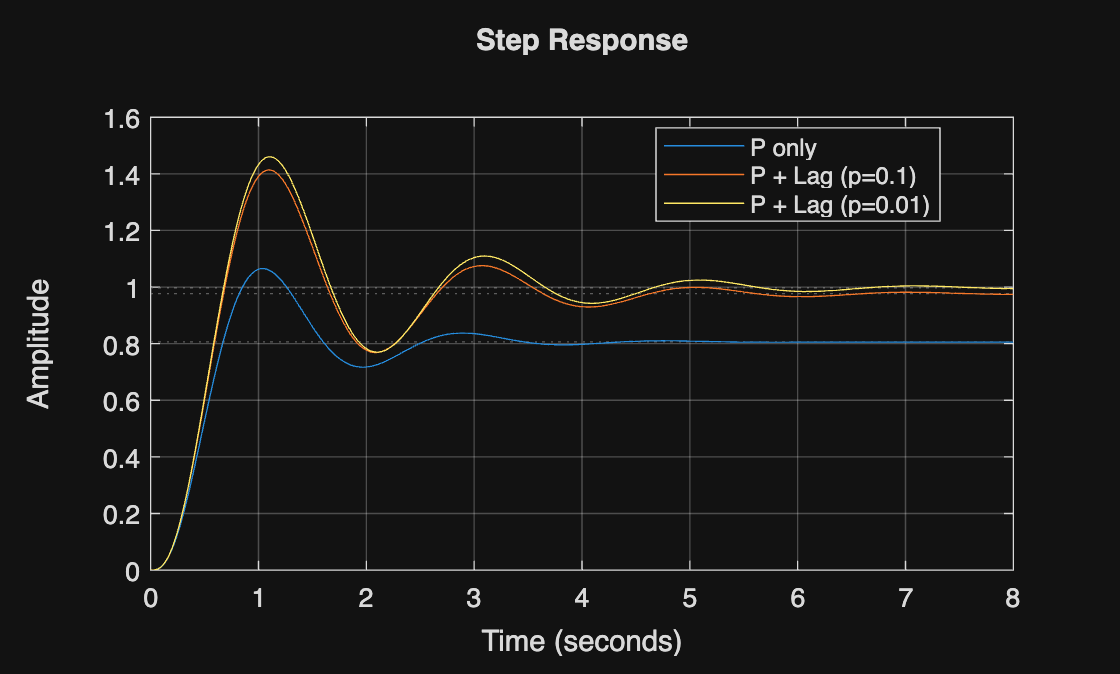

C_lag2 = (s + 1)/(s + 0.01);
C1 = Cp * C_lag2;
sys3 = feedback(C1 * G, 1);
step(sys, sys2, sys3);
grid on;
legend('P only','P + Lag (p=0.1)','P + Lag (p=0.01)','Location','best');

Moving the lag pole closer to the origin creates a trade-off: it maximizes steady-state accuracy by boosting DC gain, but inevitably slows down the system. The increased gain ensures the output matches the reference , while the slow dynamics of the pole cause the response to 'drag,' increasing the time required to fully settle.

# Problem 3: Feedforward + Feedback Control

## Feedback-Only Control

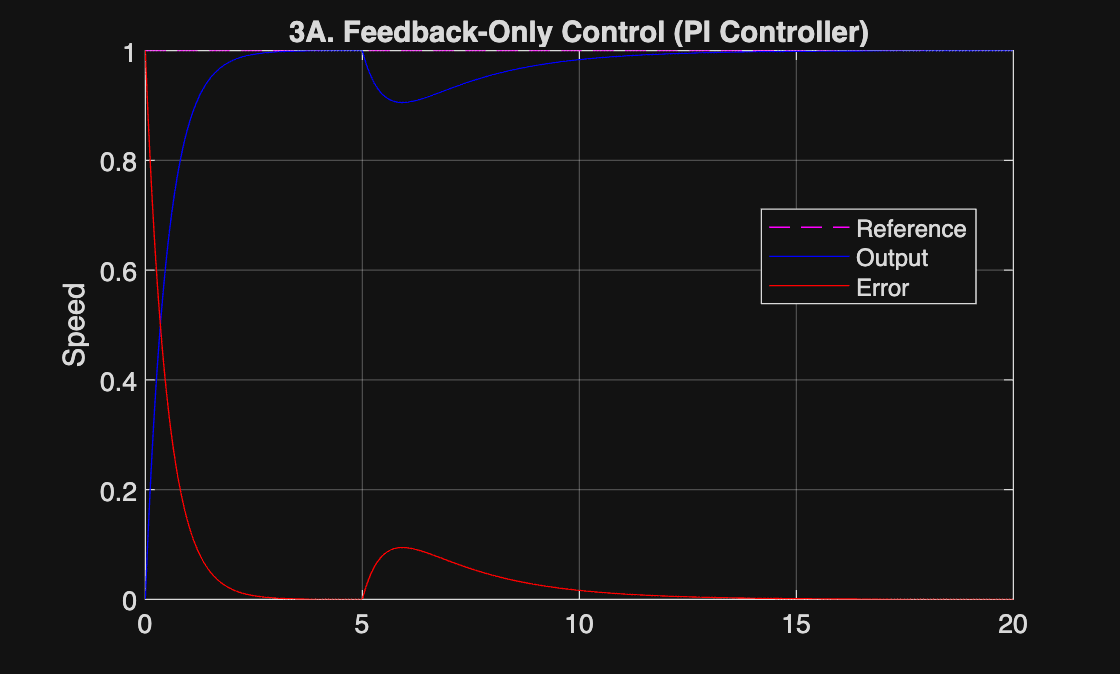

s = tf('s');
G = 1/(s + 0.5);
Kp = 2;
Ki = 1;
Cfb = Kp + Ki/s;
sys = feedback(G * Cfb, 1);
sys_d = -feedback(G, Cfb);
t = 0:0.01:20; % Time vector
d = 0.3*(t >= 5);% Disturbance
r = ones(size(t)); % Reference speed (constant)
y_r = lsim(sys,r,t); % response to reference
y_d = lsim(sys_d, d, t); % response to disturbance
yfb = y_r + y_d;
efb = r - yfb; % error

figure;
plot(t, r, 'm--', t, yfb, 'b',t,efb,'r');
grid on;
ylabel('Speed');
legend('Reference','Output','Error','Location','best');
title('3A. Feedback-Only Control (PI Controller)');

% Index at which disturbance starts
idx = t >= 5;
max_error_fb = max(abs(efb(idx))); % Maximum error 
fprintf('Maximum Error:%.2f %%/n',max_error_fb);

Maximum Error:0.09 %/n

tol = 0.02; % 2% error band
% Recovery time calculation
% All indices where error exceeds tolerance
bad_indices = find(abs(efb(idx)) > tol);
if isempty(bad_indices)
    recovery_time_fb = 0; % It never exceeded tolerance
else
    last_bad_local_idx = bad_indices(end);
    start_of_dist_idx = find(idx, 1, 'first');
    recovery_time_fb = t(start_of_dist_idx + last_bad_local_idx) - 5;
end
fprintf('Recovery Time:%.4f %%/n',recovery_time_fb);

Recovery Time:4.6100 %/n

## Adding Feedforward Control

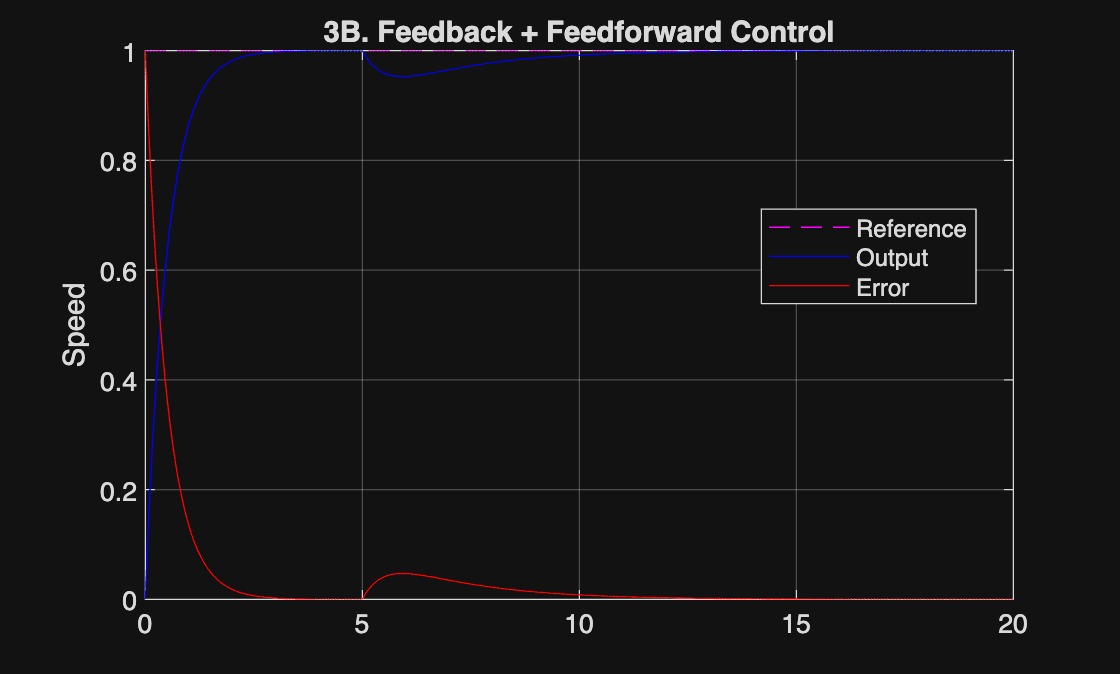

Kff = 1/dcgain(G);
uff = Kff * d; % Feedforward compensation
sys_ff = feedback(G, Cfb);
yff = lsim(sys_ff, uff, t);
y = y_r + y_d + yff;
eff = r - y; % error
figure;
plot(t, r, 'm--',t, y, 'b',t, eff, 'r');
grid on;
ylabel('Speed');
legend('Reference','Output','Error','Location','best');
title('3B. Feedback + Feedforward Control');

% Index at which disturbance starts
idx = t >= 5;
max_error_ff = max(abs(eff(idx))); % Maximum error 
% fprintf('Maximum Error:%.2f %%/n',max_error_ff);

Maximum Error:0.05 %/n

tol = 0.02; % 2% error band
% Recovery time calculation
% All indices where error exceeds tolerance
bad_indices = find(abs(eff(idx)) > tol);
if isempty(bad_indices)
    recovery_time_ff = 0; % It never exceeded tolerance
else
    last_bad_local_idx = bad_indices(end);
    start_of_dist_idx = find(idx, 1, 'first');
    recovery_time_ff = t(start_of_dist_idx + last_bad_local_idx) - 5;
end
% fprintf('Recovery Time:%.4f %%/n',recovery_time_ff);

Recovery Time:3.2100 %/n

## Performance Comparison

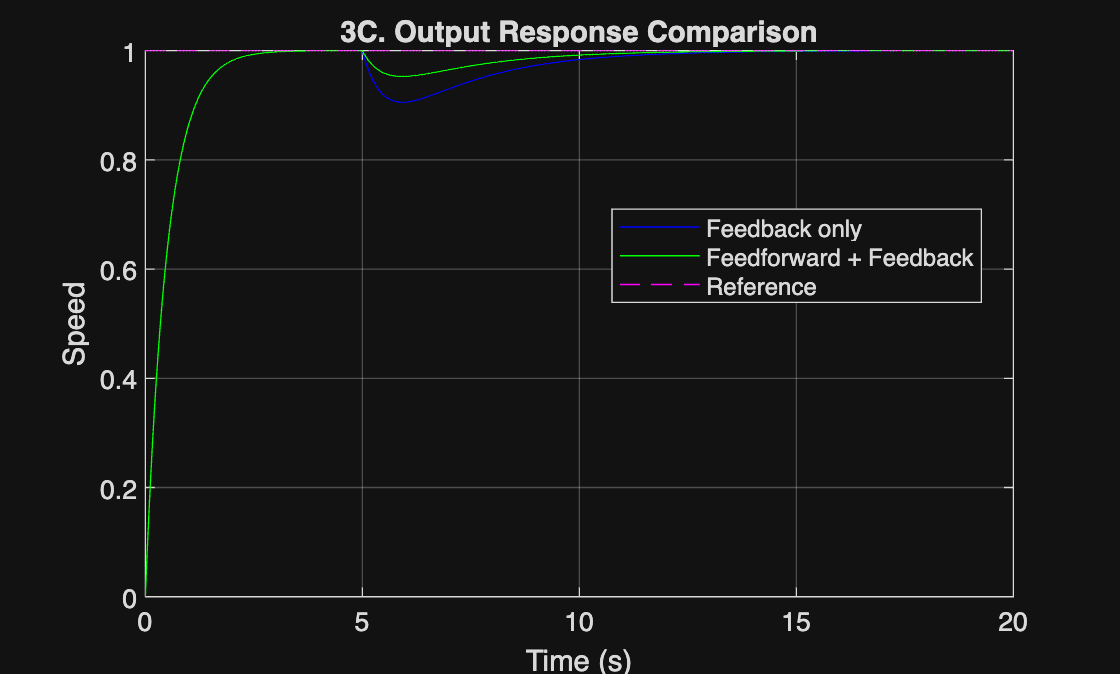

% % Feedback-only response
% y_r_fb = lsim(T_r,r,t);
% y_d_fb = lsim(T_d,d,t);
% y_fb = y_r_fb + y_d_fb;
% e_fb = r - y_fb;
% % Feedforward + feedback
% u_ff = Kff*d;
% y_ff = lsim(G,u_ff,t);
% y_fffb = y_r_fb + y_d_fb + y_ff;
% e_fffb = r - y_fffb;
%output comparision
figure;
plot(t,yfb,'b',t,y,'g',t,r,'m--'); 
grid on;
xlabel('Time (s)');
ylabel('Speed');
legend('Feedback only','Feedforward + Feedback','Reference','Location','best');
title('3C. Output Response Comparison');

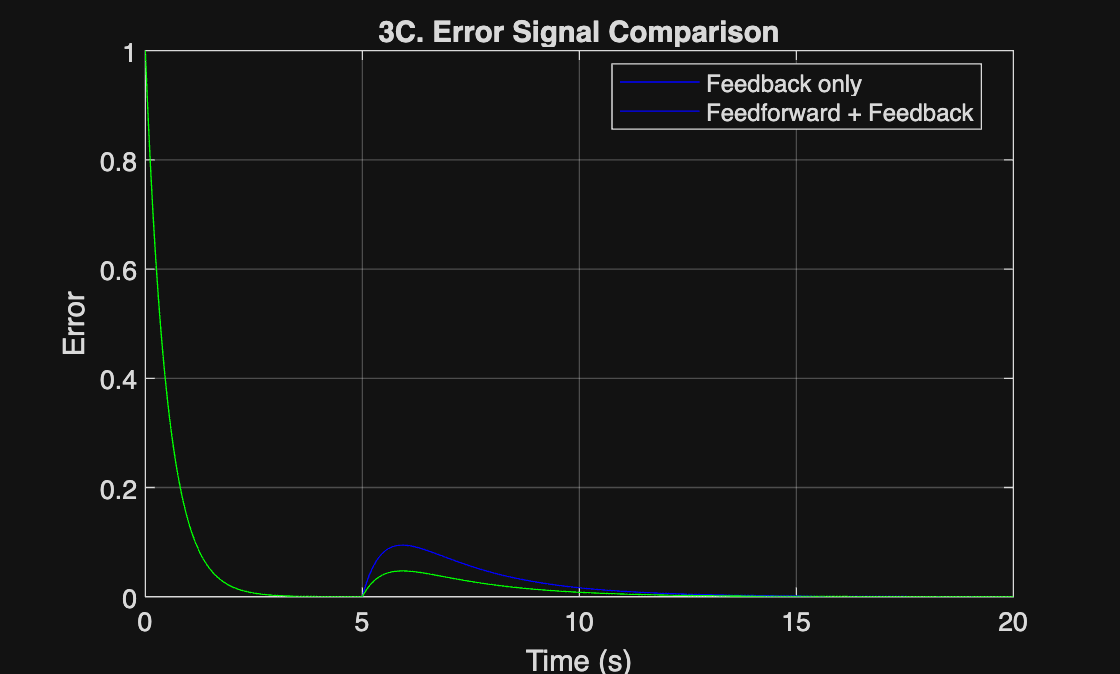


figure;
plot(t,efb,'b',t,eff,'g'); 
grid on;
xlabel('Time (s)');
ylabel('Error');
legend('Feedback only','Feedforward + Feedback','Location','best');
title('3C. Error Signal Comparison');


% Steady-state error after disturbance
ess_fb   = abs(efb(end));
ess_ff = abs(eff(end));
% Display Table
ResultsTable = table([max_error_fb; recovery_time_fb; ess_fb], ...
                     [max_error_ff; recovery_time_ff; ess_ff], ...
                     'VariableNames', {'Feedback only', 'Feedforward + Feedback'}, ...
                     'RowNames', {'Maximum Error', 'Recovery Time (s)','Steady-state error'});
disp(ResultsTable);

                          Feedback only    Feedforward + Feedback
                          _____________    ______________________

    Maximum Error              0.0945              0.047254      
    Recovery Time (s)            4.61                  3.21      
    Steady-state error     0.00011062            5.5308e-05      



Feedforward improves disturbance rejection by proactively canceling known disturbances before they affect the system output, while feedback handles residual errors and uncertainty.

## Unpredicted Disturbance Test

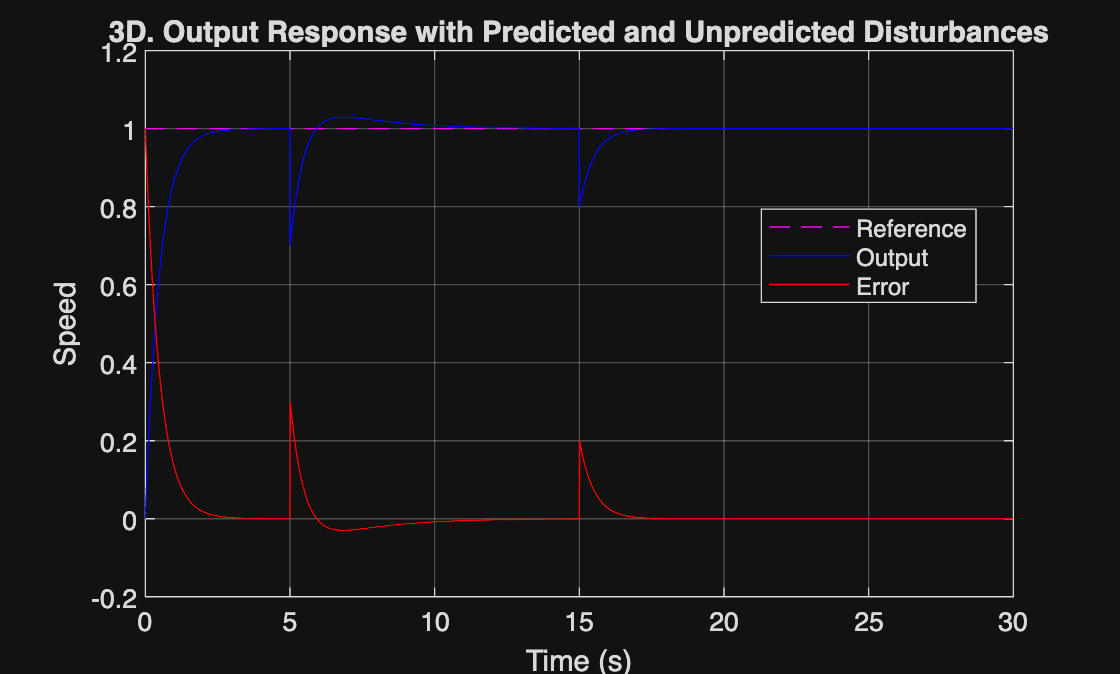

% Time
t = 0:0.01:30;
% Reference
r = ones(size(t));
% Disturbances
d1 = 0.3*(t >= 5); % predicted
d2 = 0.2*(t >= 15); % unpredicted
d  = d1 + d2;
% Plant
A = -0.5;
B = 1;
C = 1;
D = 0;
% Feedback controller gains
Kp = 2;
Ki = 1;
x = 0; % plant state
xi = 0; % integrator state
y = zeros(size(t));
e = zeros(size(t));
% Feedforward gain
Kff = 1/2;
for k = 1:length(t)-1
    % Error
    e(k) = r(k) - y(k);
    % Integrator update
    xi = xi + e(k)*0.01;
    % Feedback control
    ufb = Kp*e(k) + Ki*xi;
    % Feedforward control (only predicted disturbance)
    uff = Kff * d1(k);
    % Total control input
    u = ufb + uff;
    % Plant dynamics with disturbance at output
    dx = A*x + B*u;
    x = x + dx*0.01;
    y(k+1) = C*x - d(k);
end
e(end) = r(end) - y(end);
figure;
plot(t,r,'m--',t,y,'b',t,e,'r'); 
grid on;
xlabel('Time (s)');
ylabel('Speed');
legend('Reference','Output','Error','Location','best');
title('3D. Output Response with Predicted and Unpredicted Disturbances');

At t = 5 s (predicted disturbance), there is minimal or no error spike. The feedforward cancels disturbance before it affects the output.

At t = 15 s (unpredicted disturbance), error spike appears. The feedback controller reacts and error is driven back to zero. This proves that Feedforward alone is insufficient and feedback is needed.

When the predicted disturbance occurs, feedforward compensation prevents a speed drop by applying the required control action in advance. However, when an unpredicted disturbance is introduced, feedforward provides no compensation, and a speed error appears. 

The feedback controller then reacts to this error and restores the desired speed. This demonstrates the complementary nature of feedforward and feedback control: 

    Feedforward improves disturbance rejection when disturbances are known, while Feedback ensures robustness to unknown        disturbances.

# Problem 4: Simple MIMO System Control

## Open-Loop MIMO Analysis

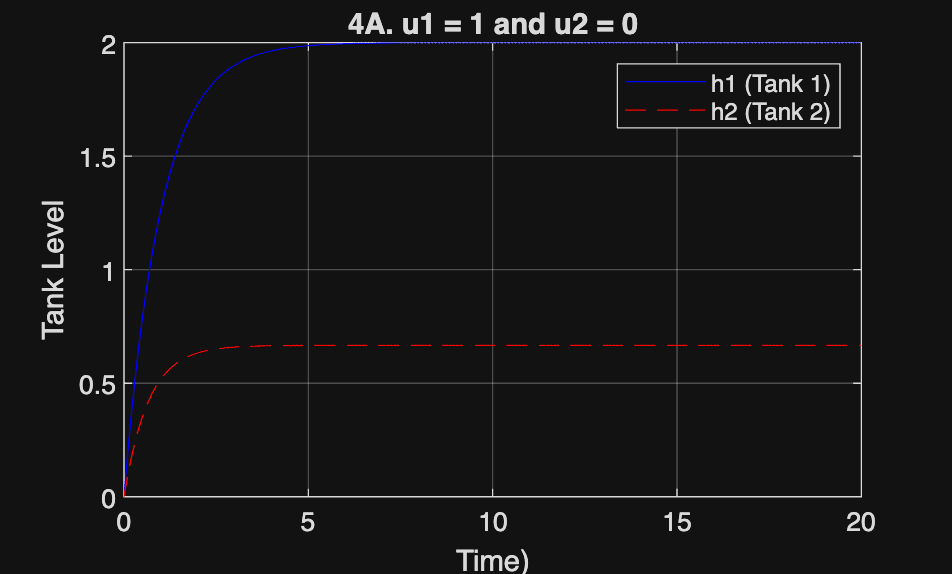

%% Define MIMO Plant (Continuous-Time)
G11 = tf(2, [1 1]);
G12 = tf(0.5, [1 2]);
G21 = tf(1, [1 1.5]);
G22 = tf(3, [1 1]);
G = [G11 G12; G21 G22];
% Step Inputs (u1=1 and u2=0)
t = 0:0.01:20;
u1 = ones(size(t));
u2 = zeros(size(t));
u = [u1; u2]'; 
[y, t] = lsim(G, u, t);
% Plot
figure;
plot(t, y(:,1), 'b-', t, y(:,2), 'r--');
legend('h1 (Tank 1)','h2 (Tank 2)');
grid on;
title('4A. u1 = 1 and u2 = 0');
xlabel('Time(s)'); 
ylabel('Tank Level');

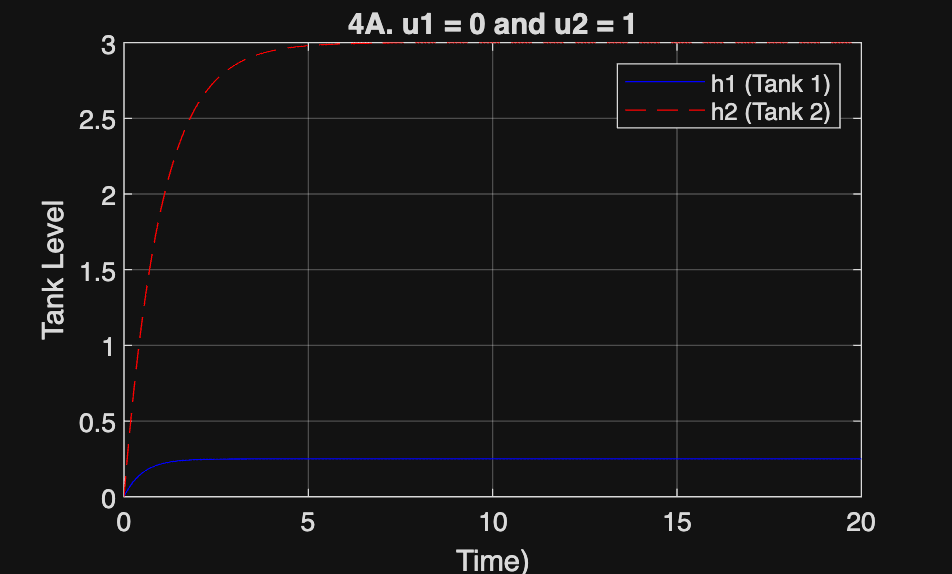

% Step Inputs (u1=1 and u2=0)
t = 0:0.01:20;
U1 = zeros(size(t));
U2 = ones(size(t));
U = [U1; U2]';
[y2, t] = lsim(G, U, t);
% Plot
figure;
plot(t, y2(:,1), 'b-', t, y2(:,2), 'r--');
legend('h1 (Tank 1)','h2 (Tank 2)');
grid on;
title('4A. u1 = 0 and u2 = 1');
xlabel('Time(s)'); 
ylabel('Tank Level');

For the given two-tank system, 

h1(s) = G11(s) . u1(s) + G12(s) . u2(s)

h2(s) = G21(s) . u1(s) + G22(s) . u2(s)

When a step input is applied to u1, while keeping u2 = 0, the h1 increases mainly due to the direct transfer function G11(s). However, at the same time, the output h2 also changes because u1 is multiplied by the cross-coupling transfer function G21(s).

Similarly, when a step input is applied to u2 while keeping u1 = 0, the output h2 responds primarily through the direct transfer function G22(s). However, the output h1 also responds due to the cross-coupling term G12(s).

## Decentralized PI Control

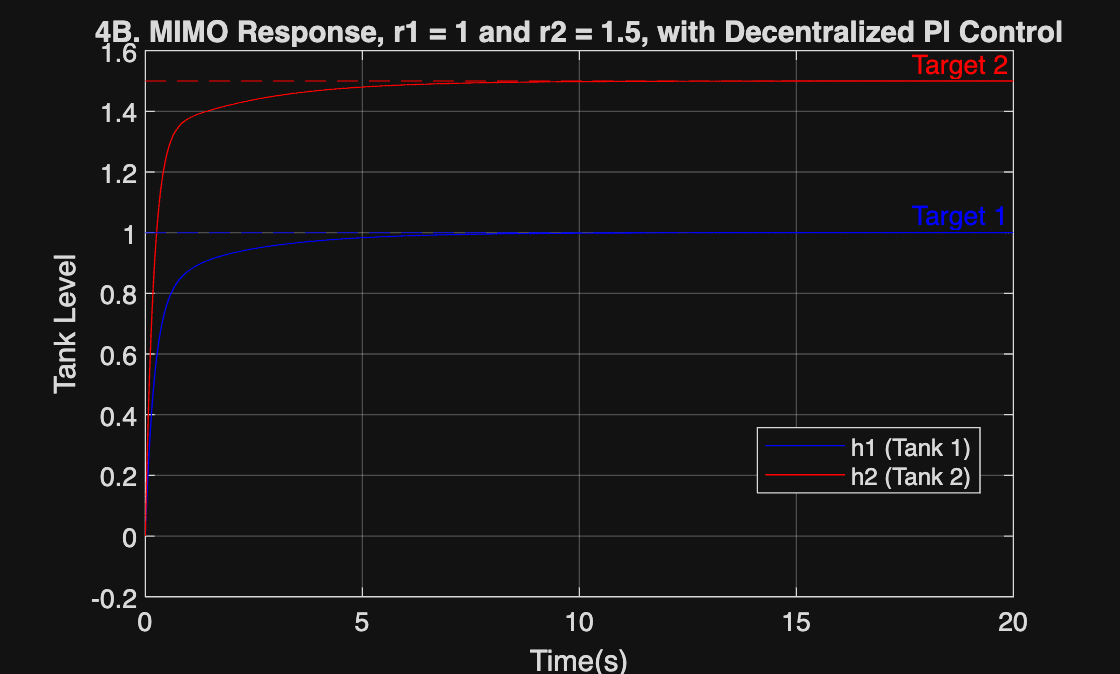

s = tf('s');
Kp1 = 1.5;
Ki1 = 0.8;  
Kp2 = 1.2; 
Ki2 = 0.6;
C1 = Kp1 + Ki1/s;
C2 = Kp2 +Ki2/s;

% references
t = 0:0.01:20;
r1 = ones(size(t))*1.0;
r2 = ones(size(t))*1.5;
r = [r1;r2]';

h1 = feedback(G11 * C1,1);
h2 = feedback(G22 * C2,1); 
G = [G11 G12; G21 G22];
C =[C1,0;0,C2];
T = feedback(G*C, eye(2));
% Tank levels simulation
[y,t] = lsim(T, r, t);
% Control signals
Tsig = feedback(C, G);
[u, ~] = lsim(Tsig, r, t);
% Plot Tank Level
figure;
plot(t, y(:,1), 'b', t, y(:,2), 'r');
yline(1.0, 'b--', 'Target 1');
yline(1.5, 'r--', 'Target 2');
grid on;
legend('h1 (Tank 1)','h2 (Tank 2)','Location','best');
title('4B. MIMO Response, r1 = 1 and r2 = 1.5, with Decentralized PI Control');
xlabel('Time(s)'); 
ylabel('Tank Level');

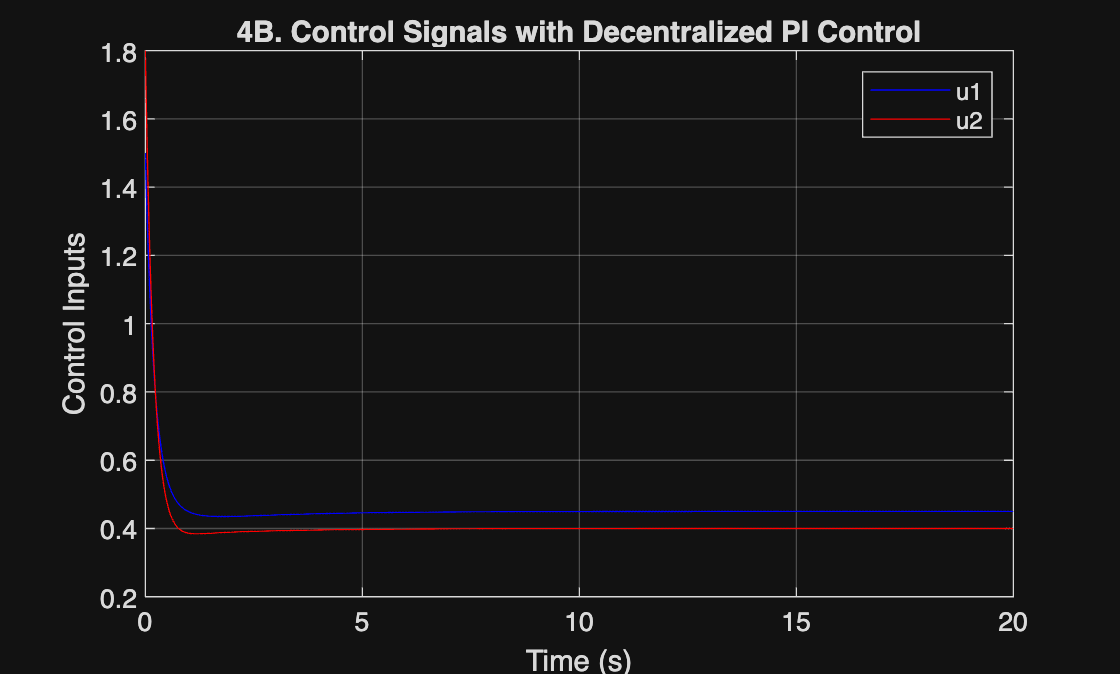

% Plot control inputs
figure;
plot(t, u(:,1), 'b', t, u(:,2), 'r');
grid on;
xlabel('Time (s)');
ylabel('Control Inputs');
legend('u1', 'u2');
title('4B. Control Signals with Decentralized PI Control');

## Analyzing Interaction Effects

- Does controlling h1 affect h2?

Yes, the control signal u1 by controller C1, intended for bringing h1 to reference r1, also affects h2 via G21 and similarly for C2, the control signal u2,  intended for bringing h2 to reference r2, affects h1 via G12. Hence producing a coupling effect.

- Do the outputs interfere with each other?

Yes, due to the coupling effect, change in one parameter also affects the other.

- Is there overshoot or oscillation due to interaction?

No overshoot or oscillations is observed in this case but it is possible to have both overshoot and oscillations due to interaction.

info_h1 = stepinfo(y(:,1), t);
info_h2 = stepinfo(y(:,2), t);
% Display Table
ResultsTable = table([y(end,1); info_h1.SettlingTime], ...
                     [y(end,2); info_h2.SettlingTime], ...
                     'VariableNames', {'h1 (Tank 1)', 'h2 (Tank 2)'}, ...
                     'RowNames', {'Steady-state value', 'Settling Time (s)'});
disp(ResultsTable);

                          h1 (Tank 1)    h2 (Tank 2)
                          ___________    ___________

    Steady-state value      0.99998           1.5   
    Settling Time (s)        4.6076        4.1058   



## Sequential Setpoint Changes

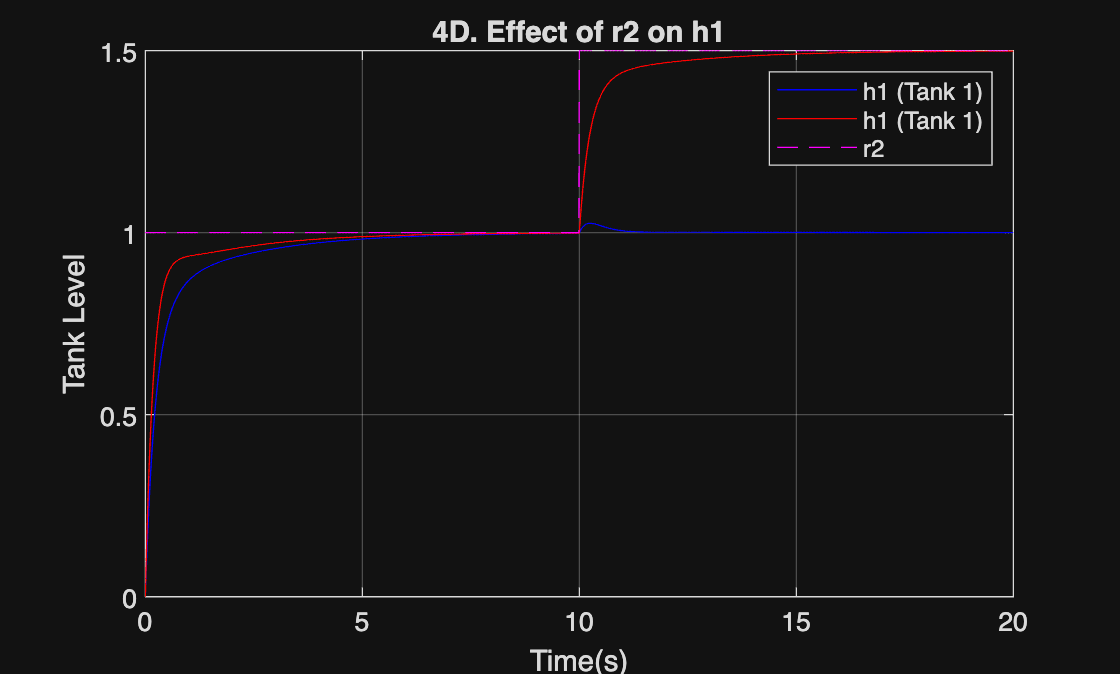

t = 0:0.01:20;
% references
r1 = ones(size(t))*1.0;
r2 = ones(size(t))*1.0;
r2(t >= 10) = 1.5;
r = [r1;r2]';
% Tank levels simulation
t = 0:0.01:20;
[y,t] = lsim(T, r, t);
% Plot
figure;
plot(t, y(:,1), 'b', t, y(:,2),'r', t, r2, 'm--');
legend('h1 (Tank 1)','h1 (Tank 1)','r2');
grid on;
title('4D. Effect of r2 on h1');
xlabel('Time(s)'); 
ylabel('Tank Level');

- Discuss why MIMO systems are more challenging than SISO systems

The challenge arise because changes in one parameter affects the others. Unlike SISO, independent controllers are not possible and the control loops will introduce disturbances in the other outputs. These interactions can lead to overshoots, oscillations, higher settling time, nerfing the overall system performance.

- Suggest how the controllers could be improved

Desiging a centralized MIMO controller, which uses errors of all the parameters hence accounting for coupling effect.

## Summary Questions

- When would you choose a lead compensator over increasing PID gains?

A lead compensator is preferred when faster transient response is required without making the system unstable or significantly increasing overshoot or noise sensitivity. Increasing PID gains can make the system unstable or overly sensitive to noise.

- What are the main advantages and limitations of lag compensators?

The primary purpose of a lag compensator is to improve steady-state accuracy and increasing the low frequency gains. The main trade-off is that it sacrifices speed for accuracy resulting in a slower system response.

- Why is feedforward control called ”proactive” compared to feedback?

Feedback systems controls only after the system has made an error while feedforward control anticipates the distubance directly and controls the system according to that, without waiting for the system to make an error.

- What makes MIMO systems more difficult to control than SISO systems?

Major challenge in controlling MIMO systems is the coupling effect. Since, unlike SISO systems, it is not possible to make independent controllers as signal change meant for one output also  affects the other outputs.